## Growth population model

**Description**: This code develops from the experimental work of SeMeCo, where a population of Protrophic cells (include the four plasmids) divide into a population mixed with Auxotrophic cells (deficient in 1 or more plasmids), see [1,2]. The code evaluates all possible populations per generation and including the probability of a given population. For instance, as illustrated in Fig.1, two population kinds (A and B) can be the result of the cell division from the Prototrophic cell in Generation 0. Both populations comprises the parent cell (Prototrophic cell), but the daughter cell can be deficient in 1 or more plasmids.

The assumptions for the cell division follows the rules:

1.Only one daughter cell is created per parent cell.

2. Daughter cells can differ from the parent in at most one plasmid. 

3.Parent cell remains unchanged (persists into next generation).

4.Growrate is the same for all cells.

5.Genotypes:

       Loss of each plasmid independently occurs with probability $p_s=0.03$. 

6.The probability of losing $n$ plasmids simultaneously is $p_s^n$.

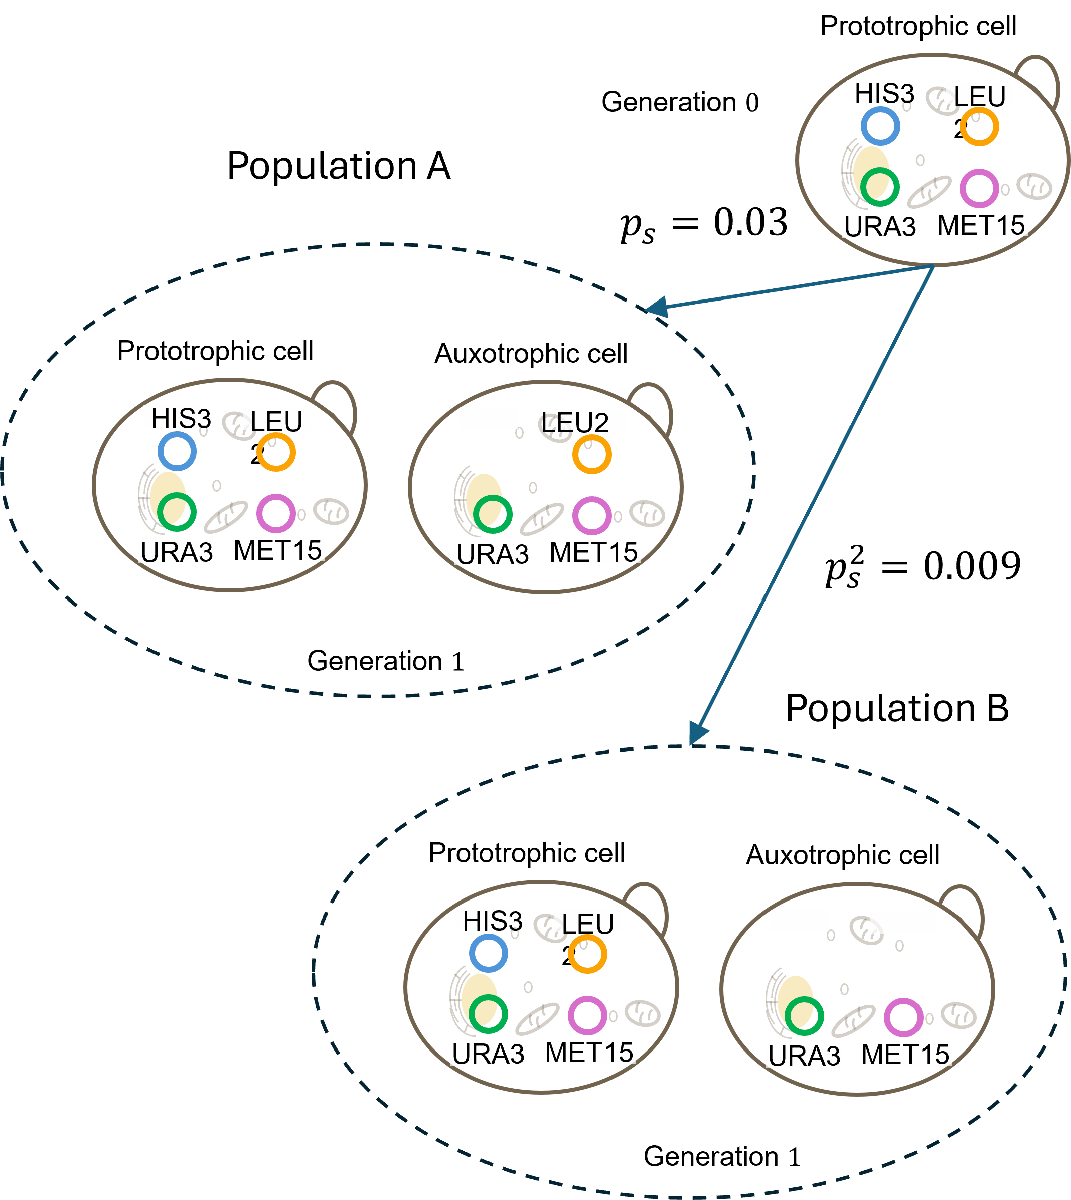

Figure 1: Illustration of two possible evolutions in the Generation $1$ from a single mother cell in Generation $0$.

close all;
clear all;
clc;

%Parameters
% Define the plasmids
plasmid_names = {'HIS3', 'LEU2', 'URA3', 'MET15'};

%Prototrophic cells have genotype 15 (1111 binary); auxotrophs have genotype < 15:
maxGenerations = 3; % Adjust carefully due to rapid population growth
p_s = 0.03;        % plasmid-loss probability parameter (adjustable)
numPlasmids = 4;   % number of plasmids
genotypes = (0:15)'; % possible genotypes as integers 0-15
initialGenotype = 15; % initial cell is prototrophic (1111 binary = 15 decimal)

% Initial population: 2 prototrophic cells
initialPopulation = [initialGenotype];

font=15;
% Initialize digraph
G = digraph();
nodeID = 1;
initialLabel = mat2str(initialPopulation);
G = addnode(G, table(nodeID, {initialPopulation}, 0, 1.0, {initialLabel}, ...
    'VariableNames', {'ID', 'Population', 'Generation', 'Probability', 'Label'}));

nextNodeID = 2;


tic;
for gen = 1:maxGenerations
    disp(['Gen -> ',num2str(gen)])
    currentGenNodes = find(G.Nodes.Generation == gen-1)';
    for nodeID = currentGenNodes
        [G, nextNodeID] = addPopulationNodes(G, nodeID, genotypes, p_s, nextNodeID, numPlasmids);        
    end
    disp(['Progress ->', num2str(gen/maxGenerations*100)])

    save ./database/G_tree_single_plasmid G
end

Gen -> 1


Progress ->33.3333


Gen -> 2


Progress ->66.6667


Gen -> 3


Progress ->100


toc;

Elapsed time is 164.220976 seconds.


function binary = genotype2binary(genotype, numPlasmids)
    binary = de2bi(genotype, numPlasmids, 'left-msb');
end

function [populations, probs] = generateAllNewPopulations(parentPop, genotypes, p_s, numPlasmids)
    numParents = length(parentPop);
    possibleDaughters = cell(numParents,1);
    daughterProbs = cell(numParents,1);

    % Compute possibilities per parent
    for i = 1:numParents
        parentGeno = parentPop(i);
        validDaughters = genotypes(genotypes <= parentGeno);
        probs = zeros(length(validDaughters),1);
        for j = 1:length(validDaughters)
            if isSinglePlasmidLoss(parentGeno, validDaughters(j), numPlasmids)
                probs(j) = segregationProbability(parentGeno, validDaughters(j), p_s, numPlasmids);
            elseif validDaughters(j) == parentGeno
                % No plasmid loss case
                probs(j) = segregationProbability(parentGeno, validDaughters(j), p_s, numPlasmids);
            else
                probs(j) = 0; % Multiple plasmid loss not allowed
            end
        end
        validDaughters = validDaughters(probs>0);
        probs = probs(probs>0);
        possibleDaughters{i} = validDaughters;
        daughterProbs{i} = probs;
    end

    % Generate all daughter combinations
    [allComb{1:numParents}] = ndgrid(possibleDaughters{:});
    daughterCombos = cell2mat(cellfun(@(x) x(:), allComb, 'UniformOutput', false));

    [allProbComb{1:numParents}] = ndgrid(daughterProbs{:});
    probCombos = prod(cell2mat(cellfun(@(x) x(:), allProbComb, 'UniformOutput', false)),2);

    % Combine parents and daughters explicitly
    numComb = size(daughterCombos,1);
    populations = zeros(numComb, numParents*2);
    for k = 1:numComb
        populations(k,:) = [parentPop, daughterCombos(k,:)];
    end
    probs = probCombos;
end


function [G, nextNodeID] = addPopulationNodes(G, parentID, genotypes, p_s, nextNodeID, numPlasmids)
    parentPop = G.Nodes.Population{parentID};
    parentProb = G.Nodes.Probability(parentID);
    currentGen = G.Nodes.Generation(parentID);

    [newPopulations, probs] = generateAllNewPopulations(parentPop, genotypes, p_s, numPlasmids);

    for i = 1:size(newPopulations,1)
        pop = newPopulations(i,:);
        popProb = parentProb * probs(i);
        label = mat2str(pop);
        G = addnode(G, table(nextNodeID, {pop}, currentGen+1, popProb, {label}, ...
            'VariableNames', {'ID', 'Population', 'Generation', 'Probability', 'Label'}));
        G = addedge(G, parentID, nextNodeID);
        nextNodeID = nextNodeID + 1;
    end
end


function prob = segregationProbability(parentGeno, daughterGeno, p_s, numPlasmids)
    parentBin = genotype2binary(parentGeno, numPlasmids);
    daughterBin = genotype2binary(daughterGeno, numPlasmids);
    lost = parentBin - daughterBin;

    if any(lost < 0)
        prob = 0; % impossible to gain plasmids
        return;
    end

    numLost = sum(lost);
    
    if numLost == 0
        % Case: no plasmid lost. Probability = 1 - sum(other losses)
        % Compute sum of other cases explicitly
        prob_sum = 0;
        if (sum(parentBin)==0)%in the case that the parentBin is all auxotrophic
            prob=1; %an all auxotrophic cell always produces an all auxotrophic cell
        else
            for n = 1:sum(parentBin)
                num_cases = nchoosek(sum(parentBin), n); % number of ways to lose n plasmids
                prob_sum = prob_sum + num_cases * (p_s^n);
            end
        end
        prob = 1 - prob_sum;
    else
        prob = p_s^numLost;
    end
end

function flag = isSinglePlasmidLoss(parentGeno, daughterGeno, numPlasmids)
    parentBin = genotype2binary(parentGeno, numPlasmids);
    daughterBin = genotype2binary(daughterGeno, numPlasmids);
    lost = parentBin - daughterBin;

    if any(lost < 0)
        flag = false; % impossible to gain plasmids
    elseif sum(lost) == 1
        flag = true; % exactly one plasmid lost
    else
        flag = false; % no plasmid or multiple plasmids lost
    end
end

%%

## References

[1] K. Campbell *et al.*, “Self-establishing communities enable cooperative metabolite exchange in a eukaryote,” *eLife*, vol. 4, p. e09943, Oct. 2015.

[2] K. Campbell, L. Herrera-Dominguez, C. Correia-Melo, A. Zelezniak, and M. Ralser, “Biochemical principles enabling metabolic cooperativity and phenotypic heterogeneity at the single celllevel,” Current Opinion in Systems Biology, vol. 8, pp. 97–108, Apr. 2018, doi: 10.1016/j.coisb.2017.12.001.